# Rolling Torus

clear
syms R0 R1 m g I_s I_p real
syms q(t) theta(t) omega(t) [3,1] % q=[x;y;z] - Basis I; omega is Basis A
P_IA = spinmat([3,2],[theta1,theta2]);
I_Bg = diag([I_p,I_p,I_s]); % basis A

%LMB:
syms F_p [3,1] real %basis I
F_B = F_p + [0;0;-m*g] == m*diff(q,t,t);

%AMB:
r_pg = [R1+R0*sin(theta2);0;-R0*cos(theta2)]; %Basis A - contact point relative to center
M_Bg = cross(r_pg,P_IA.'*F_p) == I_Bg*diff(omega,t) + cross(omega-[0;0;diff(theta3,t)],I_Bg*omega);

% no-slip constraint: v_po = v_pg + v_go = 0
v_po = P_IA*cross(omega,r_pg) + diff(q,t) == 0;
a_po = diff(v_po,t);

% convert from symfun to sym:
syms q_ddot_ q_dot_ omega_dot_ [3,1] real
eqns = subs([F_B;M_Bg;a_po],[diff(q,t,t);diff(omega,t)], [q_ddot_;omega_dot_]);
eqns = subs(eqns,diff([q;theta],t),[q_dot_;[-csc(theta2),0,0;0,1,0;cot(theta2),0,1]*omega]);
eqns = subs(eqns,[q;theta;omega],[sym('q',[3,1]);sym('theta',[3,1]);sym('omega',[3,1])]);

[A,f] = equationsToMatrix(eqns,[q_ddot_;omega_dot_;F_p]);
vars = [sym('q',[3,1]); sym('theta',[3,1]); q_dot_; sym('omega',[3,1])];

clearvars -except A f vars
A=simplify(A);
f=simplify(f);

## Substitute in Values

% Dimensional parameters:
R0 = 1;
R1 = 2.5;
m = 1;

g = 9.8;

%initial conditions:
theta0 = [0;1;0];
omega0 = [1;0;3];

% simulation duration:
tf = 10;

% don't edit below this line:
%%%%%%%%%%%%%%%%%%%%%%%%%
I_s = (1/4)*m*(3*R0^2+4*R1^2);
I_p = (1/8)*m*(5*R0^2+4*R1^2);

r_pg = @(the) [R1+R0*sin(the(2));0;-R0*cos(the(2))]; %Basis A
q0 = [0;0;R0+R1*sin(theta0(2))];
q_dot0 = -spinmat([3,2],theta0([1,2])')*cross(omega0,r_pg(theta0));

## Integrate:

hA = matlabFunction(subs(A),'Vars',{vars});
hf = matlabFunction(subs(f),'Vars',{vars});
% theta-dot in terms of theta and omega:
hw = @(th,om) [-csc(th(2)),0,0;0,1,0;cot(th(2)),0,1]*om;

% z = [q;theta;q_dot;omega]
function z_dot = EOM(z,hA,hf,hw)
theta_dot = hw(z(4:6),z(10:12));
u = hA(z)\hf(z);
z_dot = [z(7:9);
         theta_dot;
         u(1:6)];
end

[t,z] = ode45(@(t,z) EOM(z,hA,hf,hw),linspace(0,tf,30*tf),[q0;theta0;q_dot0;omega0]);
z=z';

## Animate:

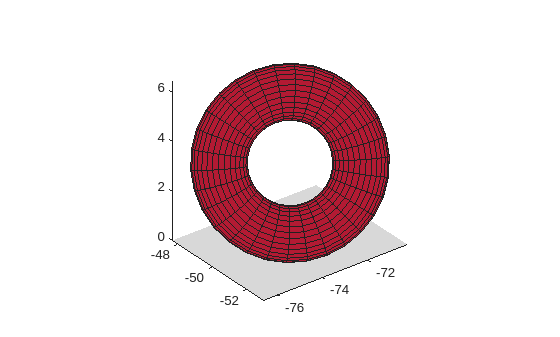

figure(1)
clf
hold on

torus = hgtransform;
% draw a torus:
n = 15;
alpha = (-n:n)/n;
X = (R1+R0*cospi(alpha)).*cospi(alpha');
Y = (R1+R0*cospi(alpha)).*sinpi(alpha');
Z = R0*sinpi(alpha).*ones(2*n+1,1);
surf(X,Y,Z,'FaceColor',[0.7,0.1,0.2],'Parent',torus)
constantplane([0;0;1],0)
axis equal

for i=1:length(t)
    set(torus,'Matrix',[spinmat([3,2,3],z(4:6,i)'),[z(1:3,i)];[0,0,0,1]])
    drawnow
end

## Check Energy:

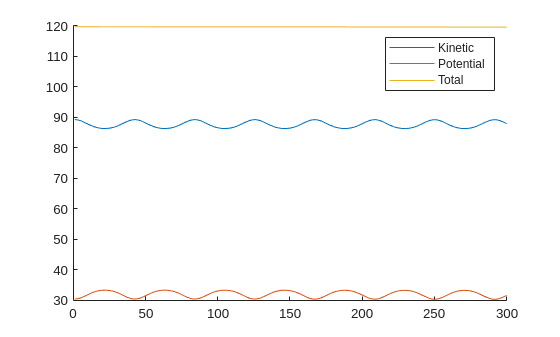

T = @(i) (1/2)*m*z(7:9,i)'*z(7:9,i) + (1/2)*z(10:12,i)'*diag([I_p,I_p,I_s])*z(10:12,i);
V = @(i) m*g*z(3,i);

figure(2)
clf
hold on
plot(arrayfun(T,1:length(t)),'DisplayName','Kinetic')
plot(arrayfun(V,1:length(t)),'DisplayName','Potential')
plot(arrayfun(@(i)T(i)+V(i),1:length(t)),'DisplayName','Total')
legend